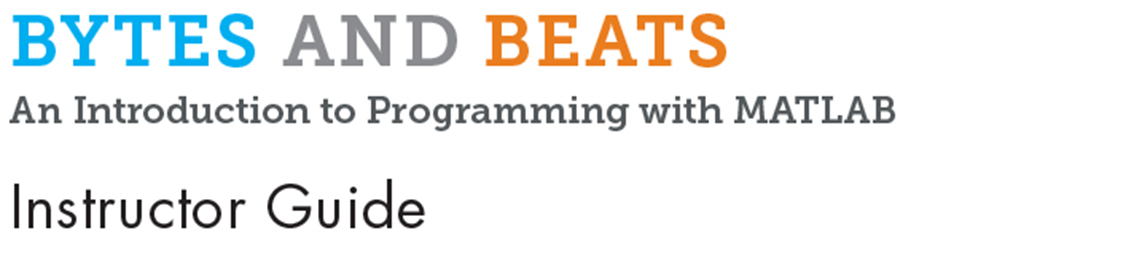

# Module 15: Creating a Melody

**Prerequisite Domain Knowledge:** Importing and editing sound files, Vector manipulation

**Expected Completion Time: **50 minutes

## Creating a Melody using Addition and Concatenation

*Expected Duration: 50 minutes*

### Learning Objectives

- Students will create a script in MATLAB® that will allow them to compose and easily create a melody 

### Motivation

This activity combines several programming concepts to compose and create a melody. The students will save it as a sound file that they can take with them. 

Spend some time on this lesson as it revisits and combines a lot of concepts.

### Materials

- MATLAB

- Worksheet “Creating a Melody”

### Solution

 
open ProcessSong_solution.mlx

### Steps

- Distribute the worksheet "Creating a Melody" and show the students the plan for the melody we want to create.

% here represents silence or that instrument is not playing. The other letters indicate the notes to be played. In case of the cabasa and tambourine, we have just one note and it is represented by the first letter of the instrument's name.

- Clear the Workspace and the Command Window:

- Tell the students to open the script "ProcessSong.mlx" by running this command in the Command Window:

 
open ProcessSong.mlx

This script has starter code which the students will complete in this activity. Each instruction in the script has a hint in form of a function name that they need to use. 

- navigate to the folder **audio_files**

- Review the first section with the students. 

- In this part, we use the `split `function to get the notes from a string into a string vector. We have completed the string input for the guitar notes. Students can run this section to observe the `guitar` variable.

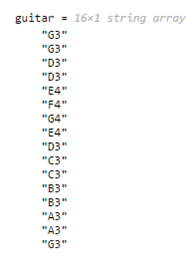

Tell the students to complete this section by filling in the string for `tambourine` and `cabasa `based on the table above. Remember to use the `split `function on the strings to get a string vector. The result should look like this:

Finally, students can run this section and observe the Workspace. Ask them to relate it to the table in their worksheet.

The variables `cabasa`, `tambourine`, and `guitar` each have 16 elements in their arrays relating to the ‘timing’ row in the Worksheet table.

For each of the 16 timesteps, we will *add* the three instruments' notes and then *concatenate* the added results one after the other. This will create our complete melody. Ensure that the students understand this process conceptually. 

Ask questions to see if they can apply previously learnt concepts to this activity:

- How will they go over all the timesteps?

-     Use a for loop that goes from 1 to 16

- How will they import the sounds from the audio files into MATLAB?

-     Use audioread() function and the sound signal will be imported as a vector of numbers. The file name we read will depend on the note from the three vectors.

- What about silence or %? 

-     Create a vector of zeros and write it to an audio file.

- How will they combine the three sounds (or notes) in each time step?

-     Simply add the three imported vectors like we did in previous lesson

- How will they append the sum to previous timesteps or how will they put the notes one after the other? (tricky concept)

-     Start with a silence vector 'song' before for loop. In each timestep, concatenate the sum to 'song' and save result back inside 'song'. This will keep the 'song' updated.

- How will the save the final vector into a sound file?

-     Use audiowrite()

Now that we have a plan of action, let the students spend some time going through the starter code. We have filled in the code like reading the guitar notes from file, for reference. Some lines or blocks have been left empty with instructions and two lines of code will need to be modified using the variables created by the students.

The lines in green are just comments to guide and can be deleted when students fill their code.

- Navigate to *audio_files*

- Direct the students to fill in code for one question or sub-question (1 to 6) at a time and discuss the answers for each.

- Create string vectors of same length for different instruments ( split() )

cabasa = split("C C C C C C C % C C C C C C C %");
tambourine = split("T % T % T % T % T % T % T % T %");
guitar = split("G3 G3 D3 D3 E4 F4 G4 E4 D3 C3 C3 B3 B3 A3 A3 G3");

- Find total number of notes ( length() )

N = length(guitar);

- Start the song with silence to begin ( zeros() )

song = zeros(40000, 1);

- Use for loop to add all instrument notes and concatenate to song

- Start for loop from 1 to the total number of notes (from step 2)

© COPYRIGHT 2024 by The MathWorks®, Inc.